## **0. Initialization**

clc;
clear;
img_org = imread("charact2.bmp");%read the original image

## 1. Display the original image

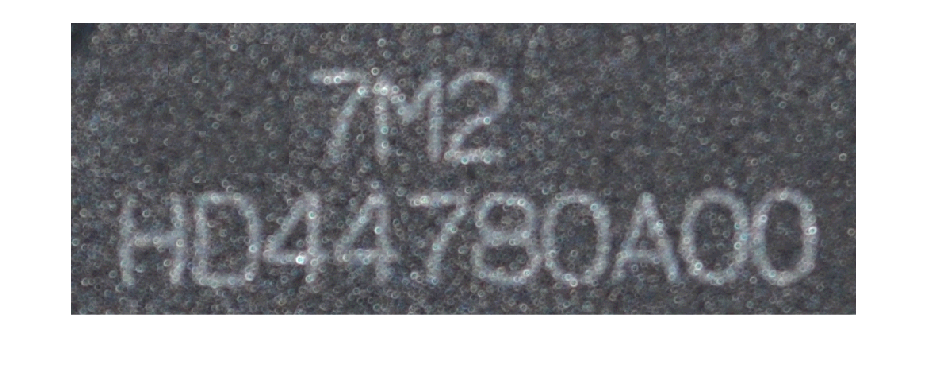

figure("Name","the original image");

imshow(img_org);

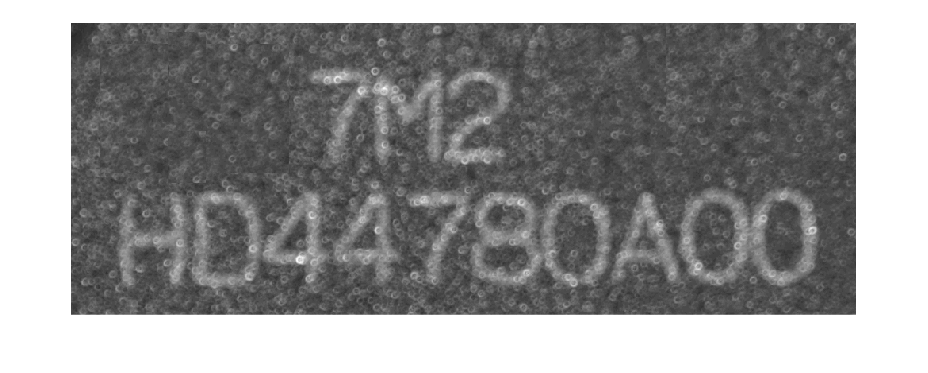

img_gray = rgb2gray(img_org);           % transform to gray image
imshow(img_gray);

## 2. Implement 3x3 averaging mask and rotating mask.Try masks in other sizes

### 2.1 Apply 3x3 averaging mask on the original image

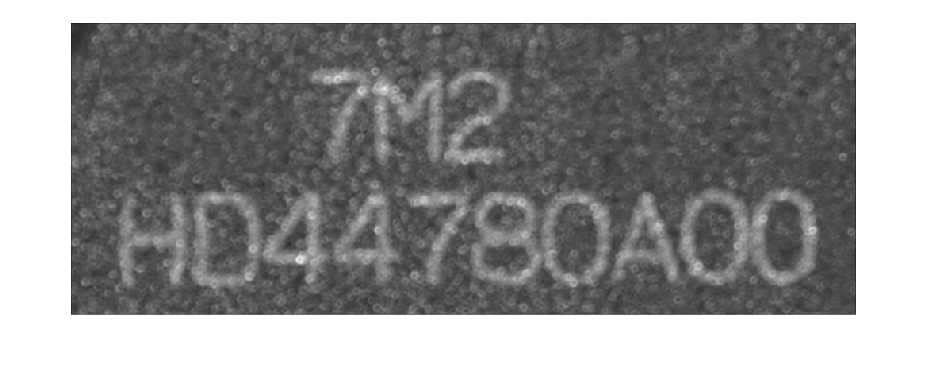

figure("Name","3x3 averaging mask image");
average_mask_3by3 = ones(3,3)./9;                           % create the mask
img_3by3average = imfilter(img_gray,average_mask_3by3);     % apply the mask

imshow(img_3by3average);                                    % display the 3x3 averaged image

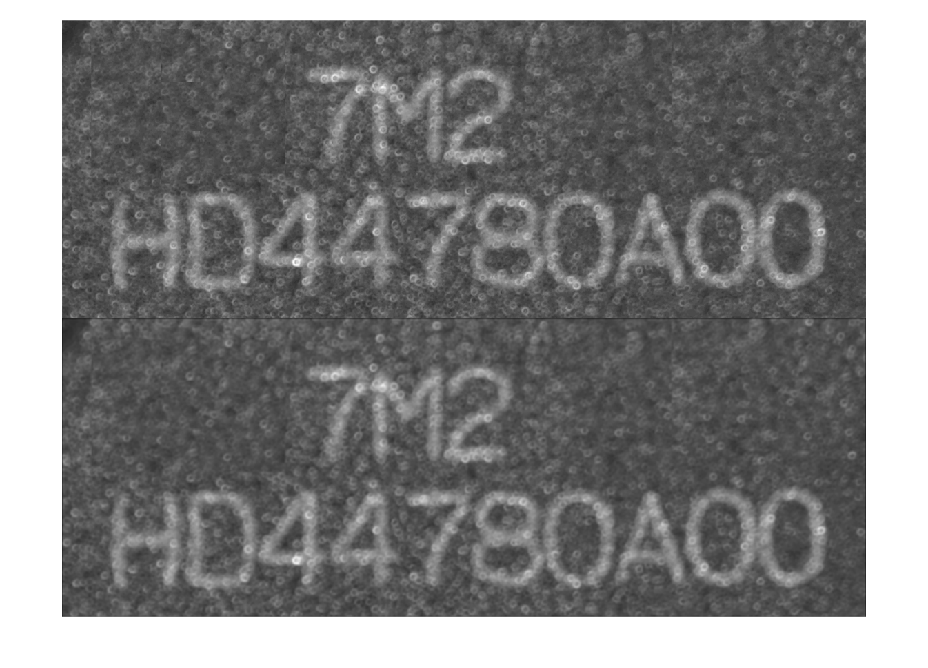

montage([img_gray; img_3by3average]);                       % compair with origin grey image

There are not many differents. In the filtered image, the colors are lighter and the image is blurrier

The results of different 3X3 convolusion kernel shows below

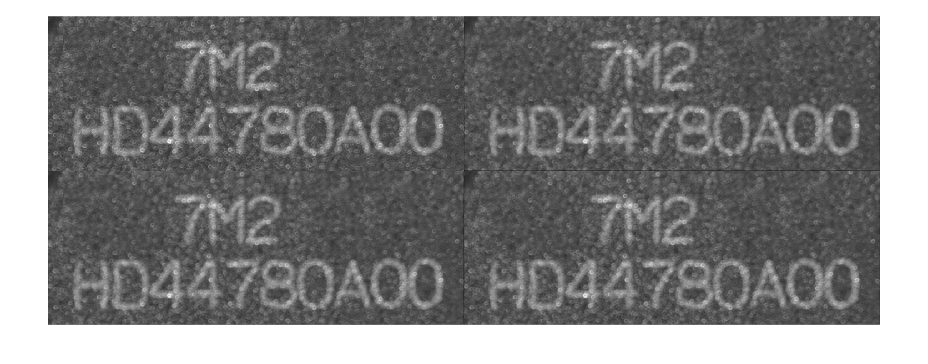

montage([  img_gray,  img_3by3average; ...
           imfilter(img_gray,([1 1 1; 1 2 1; 1 1 1]./10)), ...
           imfilter(img_gray,([1 2 1; 2 4 2; 1 2 1]./16))])

We also tried different size of filter, noticed that larger mask results more blurry

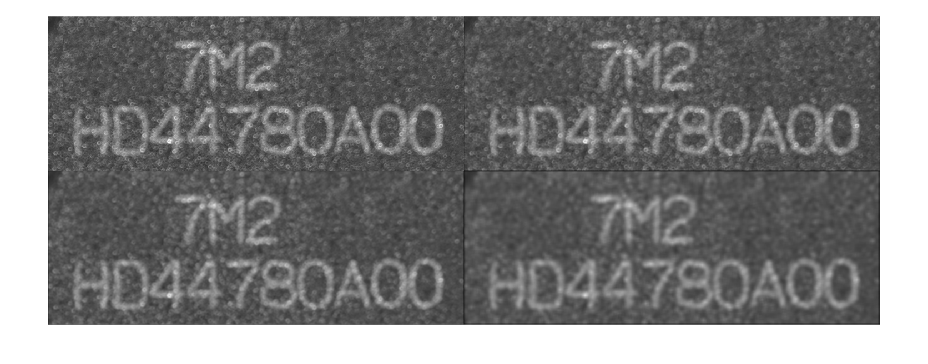

montage([   img_gray,                          img_3by3average; ...
            imfilter(img_gray,ones(5,5)./25),   imfilter(img_gray,ones(10,10)./100)]);

中值滤波器

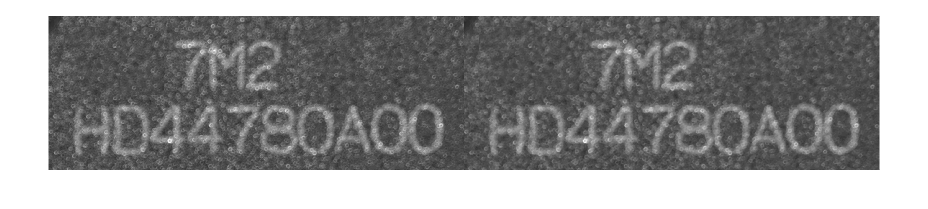

montage([img_gray, medfilt2(img_gray)])

高斯滤波器

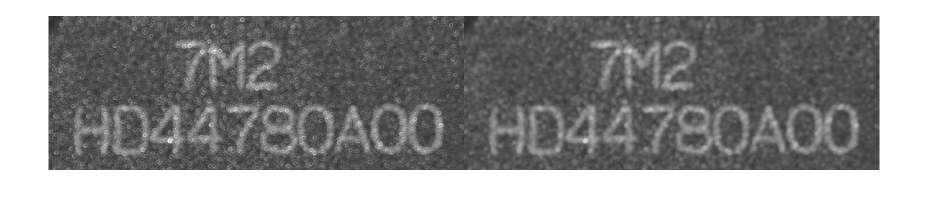

montage([img_gray, imgaussfilt(img_gray,2)])

二维自适应降噪滤波

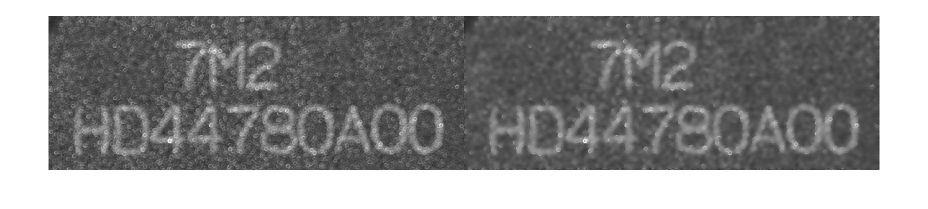

% montage([img_gray, wiener2(img_gray,[10 10])])

### 2.2 Apply 3x3 rotating mask on the original image

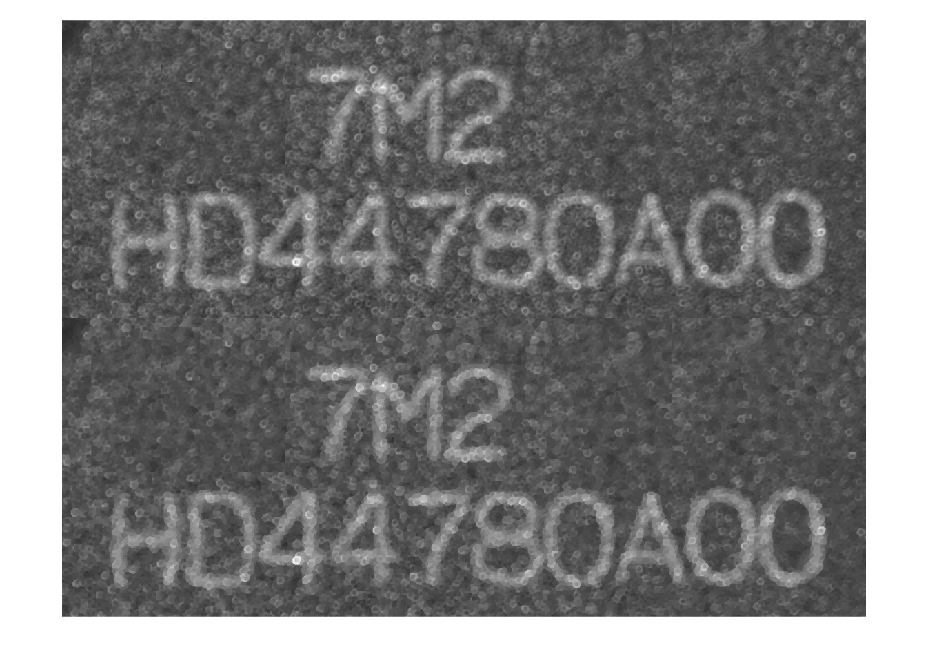

img_3X3rotate = img_gray;
img_size = size(img_gray);
height = img_size(1);
width = img_size(2);

for i = 3: height-2
    for j = 3: width-2

        min_dispersion = inf;
        min_mean = inf;

        for k = -1:1
            for l = -1:1
                % 提取mask
                sub_matrix = img_gray(i+k-1:i+k+1, j+l-1:j+l+1);
                
                % 计算mask内所有像素的平均灰度
                mean_intensity = mean2(sub_matrix);

                % 计算mask内所有像素的标准差（方差的开根号，可以代替用于比较方差大小）
                dispersion = std2(sub_matrix);

                if (dispersion < min_dispersion)
                    min_dispersion = dispersion;
                    min_mean = mean_intensity;
                end
            end
        end
        
        % 取值为方差最小的mask的灰度均值
        img_3X3rotate(i,j) = min_mean;

    end
end
montage([img_gray; img_3X3rotate])

## 3. Create an image which is a sub-image of the original image comprising the middle  line – HD44780A00.

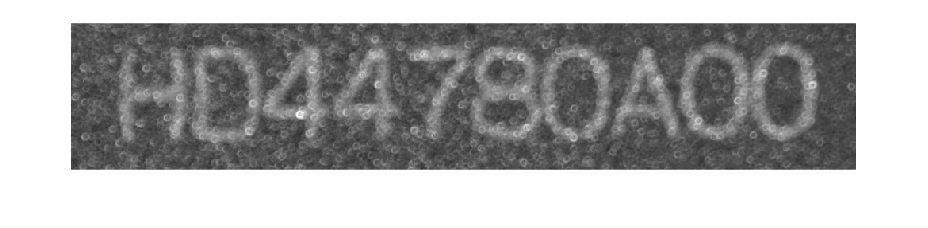

figure("Name","Cropped sub image - HD4478A00");
img_hd = imcrop(img_gray,[1 184 990 367]); %Crop a sub-image
imshow(img_hd);

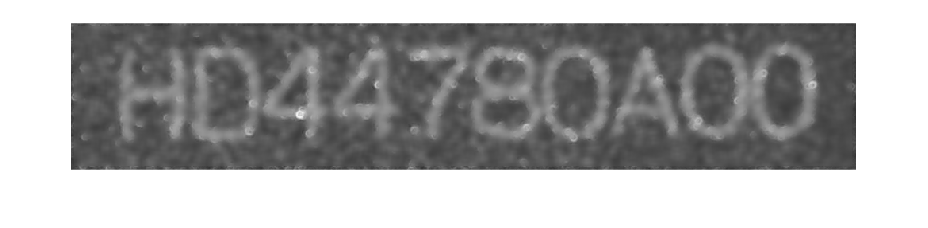

imshow(wiener2(img_hd,[10 10]))

## 4. Create a binary image from Step 3 using thresholding.

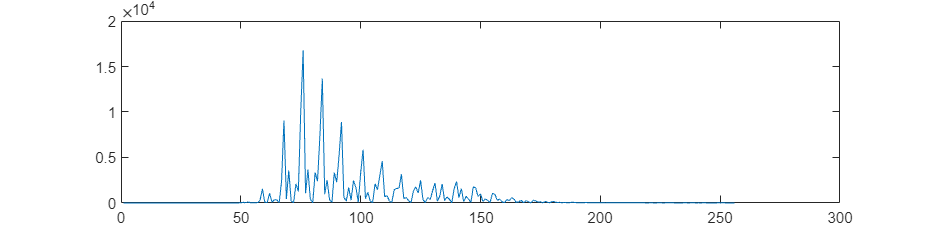

% create a gray level histogram first
plot(imhist(img_hd));           %105seems to be a good threshold value

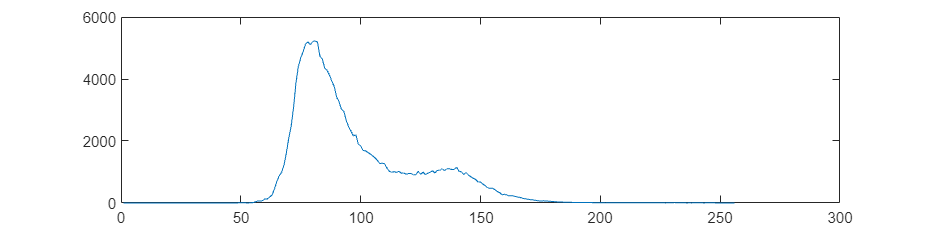

plot(imhist(wiener2(img_hd,[5 5])));

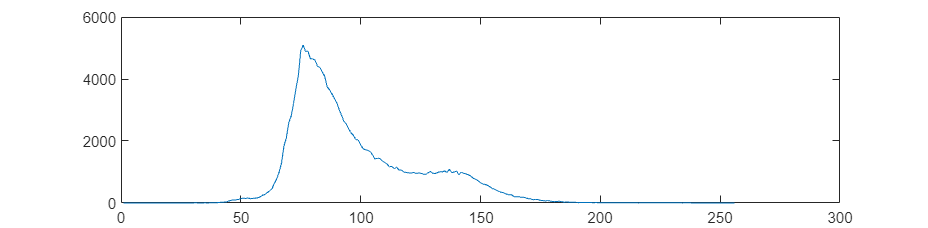

plot(imhist(imfilter(img_hd,average_mask_3by3)));

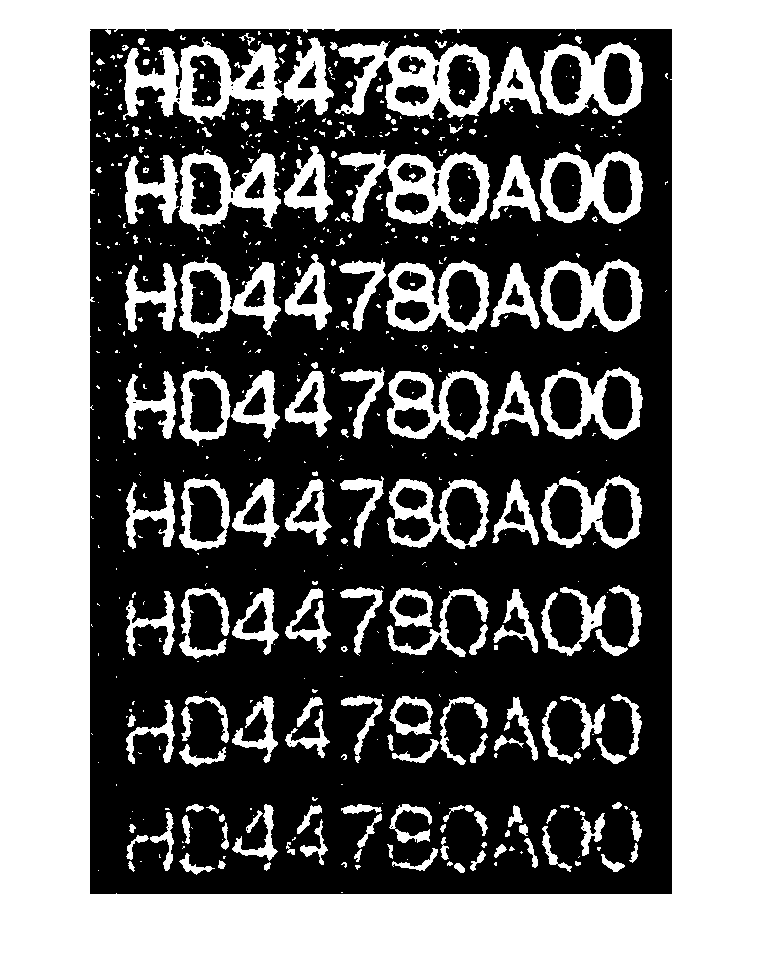

%img_hd_filtered = imfilter(img_hd,average_mask_3by3);
img_hd_filtered = wiener2(img_hd,[5 5]);

montage([   imbinarize(img_hd_filtered,100/255); ...
            imbinarize(img_hd_filtered,105/255); ...
            imbinarize(img_hd_filtered,110/255); ...
            imbinarize(img_hd_filtered,115/255); ...
            imbinarize(img_hd_filtered,120/255); ...
            imbinarize(img_hd_filtered,125/255); ...
            imbinarize(img_hd_filtered,130/255); ...
            imbinarize(img_hd_filtered,135/255);])

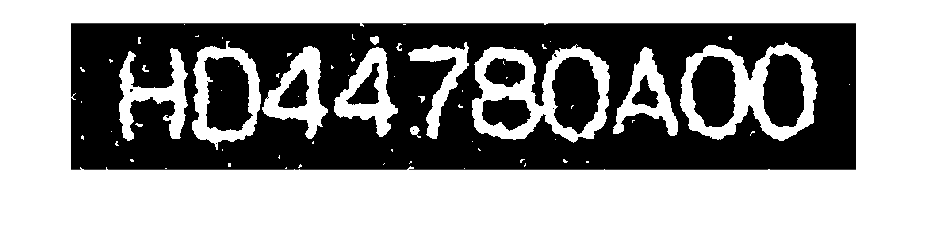

% thresgold the image
img_threshold = imbinarize(img_hd_filtered,115/255); %apply thresholding
imshow(img_threshold); %show image

## 5. Determine the outline(s) of characters in the image.

使用连通区域分割来处理连通区域

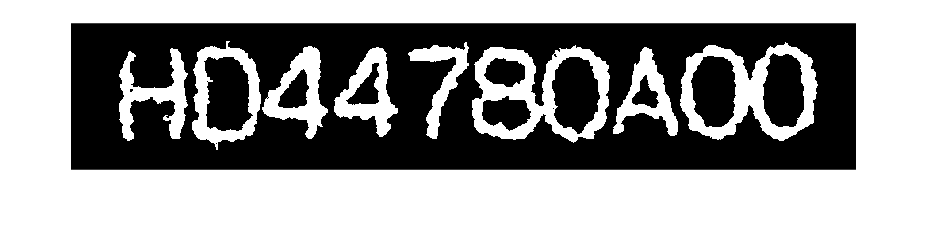

CC = bwconncomp(img_threshold);

% 计算每个连通分量的面积
stats = regionprops(CC, 'Area');

% 获取面积数组
area = [stats.Area];

% 定义阈值
threshold = 500;

% 过滤掉小于阈值的连通区域
img_threshold = bwareaopen(img_threshold, threshold);

% 显示过滤后的图像
imshow(img_threshold);

使用Sobel算子来提取边缘

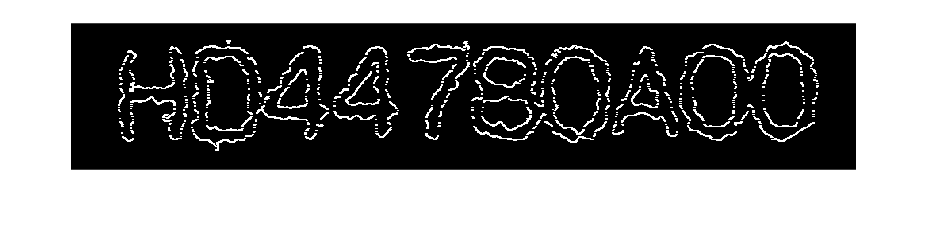

%% 创建计算水平和垂直梯度的卷积核
G_x_filter = [  -1  -2  -1;
                0   0   0;
                1   2   1];
G_x = imfilter(img_threshold,G_x_filter);
G_x_minus = imfilter(img_threshold,-G_x_filter);
imshow(G_x + G_x_minus);

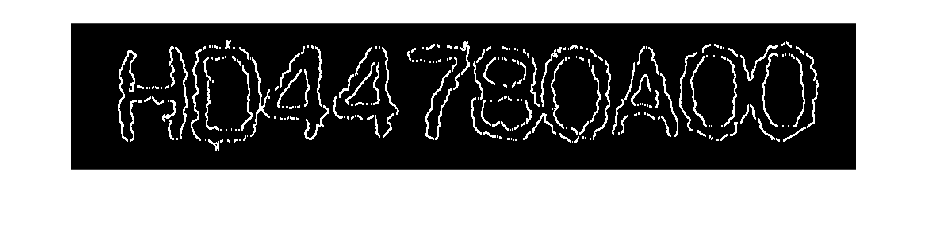

G_y_filter = [  -1  0   1;
                -2  0   2;
                -1  0   1];
G_y = imfilter(img_threshold,G_y_filter);
G_y_minus = imfilter(img_threshold,-G_y_filter);
imshow(G_y+G_y_minus);

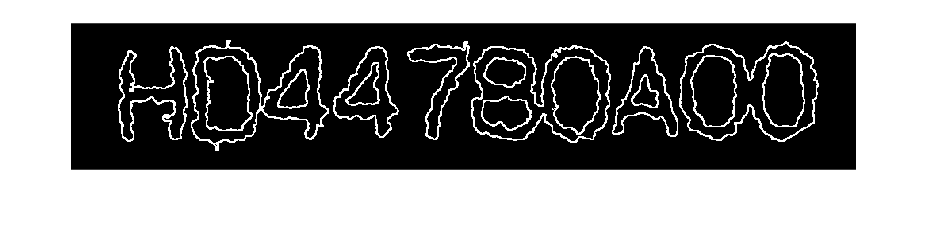

imshow(G_x+G_y+G_x_minus+G_y_minus);        % 自己手搓的Sobel边缘检测

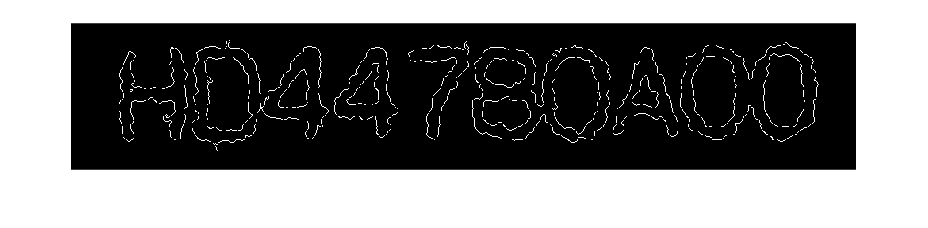

imshow(edge(img_threshold,"sobel"));        % 官方提供的Sobel边缘检测

## 6. Segment the image to separate and label the different characters

用“8-邻域”连通性来标记并分割图像区域

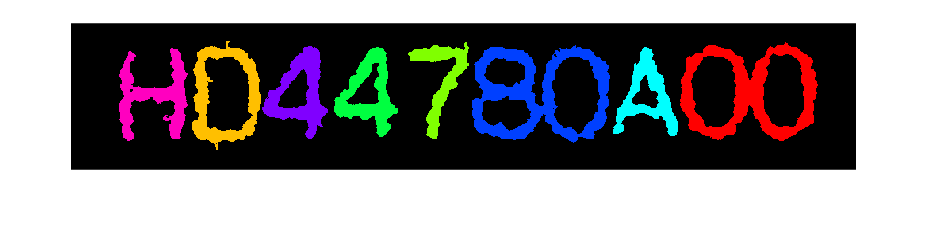

% Segmentation
labeledImage = bwlabel(img_threshold, 8); % 8-Neighborhood Region Labelling
labelProps = regionprops(logical(labeledImage), 'BoundingBox', 'Area'); % Bounding Box for each Region

% Mark the different region with color
coloredLabels = label2rgb(labeledImage, 'hsv', 'k', 'shuffle');
imshow(coloredLabels);

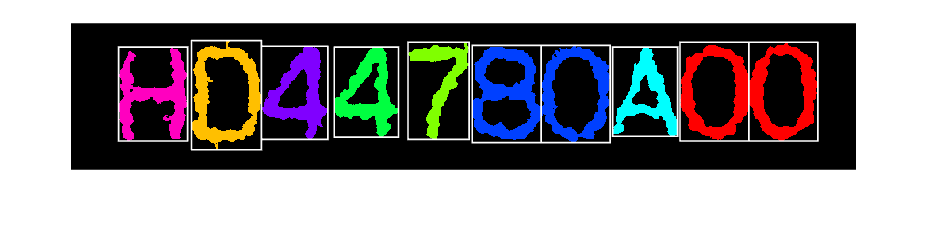

% Noise Reduction for small white area
img_denoise = img_threshold;
minArea = 300; % Area threshold value for elimination

for i = 1:numel(labelProps)
    if labelProps(i).Area < minArea
        noise = ceil(labelProps(i).BoundingBox);
        img_denoise(noise(2):(noise(2)+noise(4)-1), noise(1):(noise(1)+noise(3)-1)) = 0; 
    end
end

% Re-Segmentation
labeledImage = bwlabel(img_denoise, 8);
labelProps = regionprops(logical(labeledImage), 'BoundingBox', 'Area');

% Show the image after Noise Reduction and display the bounding box
coloredLabels = label2rgb(labeledImage, 'hsv', 'k', 'shuffle');
imshow(coloredLabels);
hold on;

threshold = 100; % Set your threshold here

newBoundingBoxes = [];
newCharacters = {};

boundingBoxes = cat(1, labelProps.BoundingBox);
for i = 1:size(boundingBoxes, 1)
    if boundingBoxes(i,3) > threshold % If the width of the bounding box is greater than the threshold
        % Split the image into two along the width
        newBoundingBoxes(end+1,:) = [boundingBoxes(i,1), boundingBoxes(i,2), boundingBoxes(i,3)/2, boundingBoxes(i,4)];
        newBoundingBoxes(end+1,:) = [boundingBoxes(i,1) + boundingBoxes(i,3)/2, boundingBoxes(i,2), boundingBoxes(i,3)/2, boundingBoxes(i,4)];
        character1 = imcrop(labeledImage, newBoundingBoxes(end-1,:));
        character2 = imcrop(labeledImage, newBoundingBoxes(end,:));
        newCharacters{end+1} = character1;
        newCharacters{end+1} = character2;
    else
        newBoundingBoxes(end+1,:) = boundingBoxes(i,:);
        character = imcrop(labeledImage, newBoundingBoxes(end,:));
        newCharacters{end+1} = character;
    end
end

for i = 1:size(newBoundingBoxes, 1)
    rectangle('Position', newBoundingBoxes(i,:), 'EdgeColor', 'w', 'LineWidth', 1);
end
hold off;

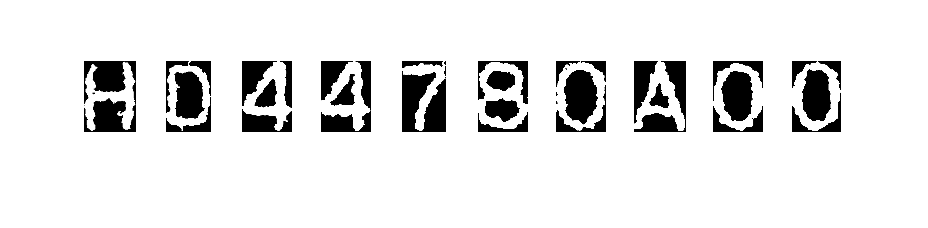


characters = cell(size(boundingBoxes, 1), 1);

for i = 1:size(newBoundingBoxes, 1)
    montage(newCharacters, 'Size', [1, length(newCharacters)], 'BorderSize', [80 40],'BackgroundColor','w');
    hold on;
end
hold off;

% Store Images
for i = 1:10
    characterFileName = sprintf('character_%d.png', i);
    black_background = zeros(128);
    black_background(1+4:size(newCharacters{i},1)+4,1+20:size(newCharacters{i},2)+20) = newCharacters{i};
    image1_resized = ~ black_background(1:128,1:128);
    imwrite(image1_resized, characterFileName);
end


## **7. Classification of characters in image**

% Import images, remember to change folder path before using
% Store trainning data
imageDS_train = imageDatastore("D:\MATLAB_codes\ME5411\img_train","IncludeSubfolders",true, ...
    'FileExtensions', {'.png'}, 'LabelSource', 'foldernames');
imageDS_train = shuffle(imageDS_train);
% Store test data
imageDS_test = imageDatastore("D:\MATLAB_codes\ME5411\img_test","IncludeSubfolders",true, ...
    'FileExtensions', {'.png'}, 'LabelSource', 'foldernames');
% DataStore image 1 characters
imageDS_image1 = imageDatastore("D:\MATLAB_codes\ME5411",'FileExtensions', {'.png'}, 'LabelSource', 'foldernames');
imageDS_image1.Labels = categorical(["H","0","D","4","4","7","8","0","A","0"]);

### **Task 1: Design a CNN to classify each characters in Image 1**

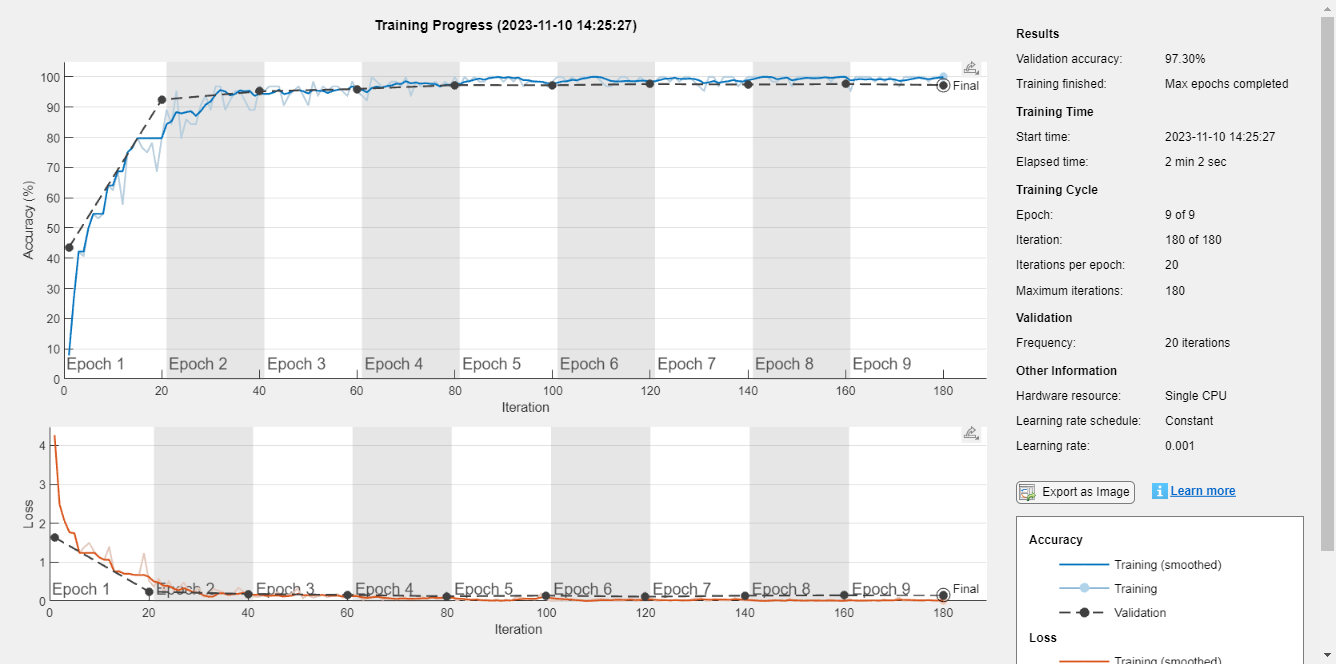

% Set up CNN
layers = [
    imageInputLayer([128,128,1])
    
    convolution2dLayer(3,8,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,8,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,128,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,256,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    dropoutLayer

    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];

options = trainingOptions("adam","InitialLearnRate",0.001,"MaxEpochs",9,"Shuffle","every-epoch", ...
    "ValidationData",imageDS_test,"ValidationFrequency",20,"MiniBatchSize",64,"Verbose",false, ...
    "ExecutionEnvironment","auto","Plots","training-progress");

net = trainNetwork(imageDS_train,layers,options);

% Classify from image 1
image1_prediction = classify(net,imageDS_image1);
image1_accuray = sum(image1_prediction == imageDS_image1.Labels) / numel(image1_prediction)

image1_accuray = 0.1000